clear all

%solving ODE numerically
x(1) = 0; %declaring first x value
h = 0.05; %step size, this can be tweaked to increase or reduce accuracy.
tf = 12; %upper time limit
t = 0:h:tf; %time range

%for loop
for i=1:tf/h
    
    x(i+1) = x(i) + h*(4-.5*x(i));
    
end

plot(t,x,".") % plotting function

%beautifying
box off

%labelling graph
xlabel("t")
ylabel("x(t)")
title("Numerical vs Analytical solution for ODE")

%plotting analytical solution
syms T %declaring time as being different to t array above

sol(T) = 8 * (1 - exp(-.5*T))

hold on %plotting on same graph
fplot(sol , [0 tf], "r") %plotting analytical solution
hold off

%adding legend
legend("Numerical soliution","Analytical solition")

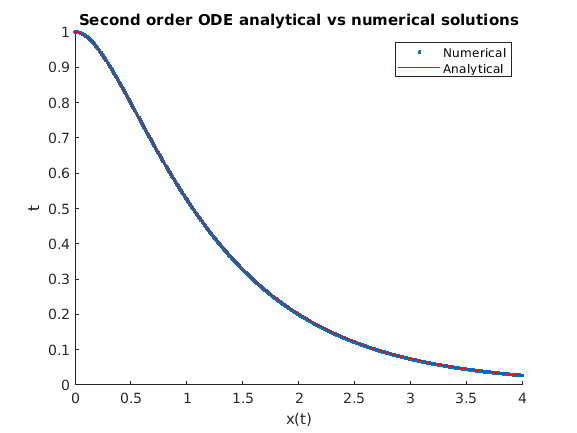

%Second order ODE numerically
clear all

%solving ode numerically
%stating initial conditions
x(1) = 1;
y(1) = 0;

%declaring size of step
h = 0.1;
tf = 4; %final time
t = 0:h:tf;

%initilizing for loop
for i = 1:tf/h
    
    x(i+1) = x(i) + h*(y(i));
    
    y(i+1) = y(i) + h*(-4*y(i) -3*x(i));
    
end

plot(t,x,".") %plotting function

syms T %declaring different T from array t

sol(T) = .5*(3*exp(-T) - exp(-3*T)); %analytical solution

hold on %plotting on same graph

fplot(sol,[0 tf],"r") %plotting analytical solution

hold off

box off %removing box

%labelling graph
xlabel("x(t)")
ylabel("t")
title("Second order ODE analytical vs numerical solutions")
legend("Numerical","Analytical")